# 2D Grating Coupler

**Grating coupler** is widely used in photonics to couple light between an optical waveguide and free space or an optical fiber. By simulating the scattering field, this example provides insights into how light interacts with the grating structure, including reflection, transmission, and diffraction.

In this example, we demonstrate the scattering field of a **2D grating coupler**. Wave is injected towards and propagates along the $+x$ direction. The relative permittivity is uniform along $y$ direction, i.e.,  $\varepsilon_r=\varepsilon_r(z,x)$. All materials in the simulation are assumed to be linear, homogeneous, and isotropic (LHI).

### Step 0: Global settings

The simulation begins by initializing the `Model2D` instance and setting the global parameters. The working plane is defined as the $\mathit{\mathbf{z}}-\mathit{\mathbf{x}}$** plane**, which aligns with the grating coupler's cross-sectional geometry. 

modelGC = Model2D.initialize();

Model2D: Object Reset and Initialized


modelGC.setLabel('zx'); % work on z-x plane

The background is designed as air, which is the defualt setting of background.

### Step 1: Simulation device

This step constructs the simulation domain by adding the key components of the grating coupler: the silicon dioxide background, periodic gratings, the grating substrate, and the output waveguide.

#### 1.1 Geometry parameters

The geometry of the grating coupler consists of periodic etches (grating features), a substrate, and an output waveguide. The grating is characterized by its **etch height**, **etch width**, and **period**, with the total grating length determined by the number of etches. The substrate forms the foundation of the device, while the output waveguide is positioned at the end of the grating structure.

% geometric parameters
h_etch = 0.2e-6; % height (in z-direction) of each grating etch
w_etch = 0.25e-6; % width (in x-direction) of each grating etch
N_etch = 15; % number of grating etches
T_grating = 0.5e-6; % period of gratings (spacing between etches)
total_grating_length = N_etch*T_grating; % total length of grating structure
h_bus = 0.25e-6; % Height (thickness) of the bus waveguide in x-direction
l_bus = (N_etch+1)*T_grating-w_etch; % Length of bus waveguide in y-direction
l_wg = 4e-6; % Length of the output waveguide in x-direction
L = l_bus+l_wg; % total length
W = 6e-6; % total width
W_sub = 4e-6; % SiO2 substrate width

#### 1.2 Material information

The grating coupler is composed of silicon for the grating and waveguide, and silicon dioxide for the cladding.

% material eps
eps_GC = 3.4^2; % Si
eps_sub = 1.44^2; % SiO2

#### 1.3 SiO2 SOI substrate

Silicon dioxide (SiO2) is the most commonly used substrate material of SOI system

modelGC.addDevice(1);
modelGC.setDevice(1).setGeometry('Rectangle', W_sub, L, 'br', [0.2e-6, -l_wg]);
modelGC.setDevice(1).setMaterial(eps_sub);

#### 1.4 Gratings

The periodic grating structure is constructed using a loop to place individual grating etches iteratively. Each etch is modeled as a polygon with defined x and y coordinates, using the permittivity of silicon. The loop ensures accurate placement of all etches, including the final one, which adjusts for its partial size. This step also demonstrates the usage of the `'Polygon'` geometry element.

z_g = [0, 0, h_etch, h_etch]+h_bus;
for ii = 1:N_etch+1
    x_start = (ii-1)*T_grating;
    
    if ii < N_etch
        x_end = x_start+w_etch;
    else
        x_end = x_start+T_grating-w_etch;
    end

    x_g = [x_start, x_end, x_end, x_start];
    
    modelGC.addDevice(ii+1);
    modelGC.setDevice(ii+1).setGeometry('Polygon', z_g, x_g);
    modelGC.setDevice(ii+1).setMaterial(eps_GC);
end

#### 1.5 Grating substrate

The grating substrate, positioned beneath the periodic etches, is modeled as a polygon. This structure supports the grating and is assigned the same permittivity as the grating material.

z_g_substrate = [h_bus, h_bus, 0, 0];
x_g_substrate = [0, l_bus, l_bus, 0];

modelGC.addDevice(N_etch+3);
modelGC.setDevice(N_etch+3).setGeometry('Polygon', z_g_substrate, x_g_substrate);
modelGC.setDevice(N_etch+3).setMaterial(eps_GC);

#### 1.6 Output waveguide

The output waveguide, placed after the grating structure. It is also modeled as a polygon and assigned the permittivity of silicon.

z_waveguide = [0, 0, h_etch+h_bus, h_etch+h_bus];
x_waveguide = [0, -l_wg, -l_wg, 0];

modelGC.addDevice(N_etch+4);
modelGC.setDevice(N_etch+4).setGeometry('Polygon', z_waveguide, x_waveguide);
modelGC.setDevice(N_etch+4).setMaterial(eps_GC);

#### 1.7 Complete device building

Once all components are added, the device is finalized using `finishDevice`, and a visual representation of the geometry is displayed with `dispImg`.

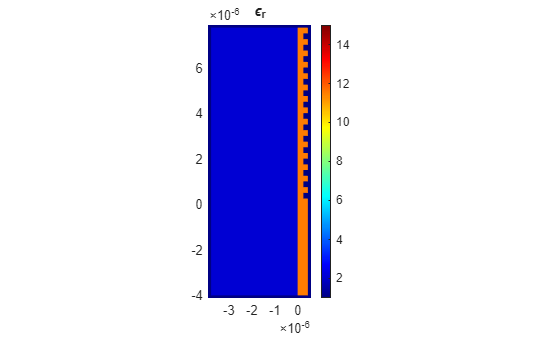

modelGC.assembleDevice;
modelGC.device.dispImg;

### Step 2: FDFD mesh grid

The FDFD solver operates on a uniform mesh grid to discretize the simulation domain. Before meshing, the geometry is represented as a `polyshape` object. After meshing, it transforms into a discrete double array that captures the spatial distribution of relative permittivity $\varepsilon_r$ and relative permeability $\mu_r$.

% mesh grid (unit: m)
dz = 20e-9; Nz = W/dz;
dx = 10e-9; Nx = L/dx;
modelGC.setMesh([Nz, Nx], [dz, dx]);

% shift mesh grid to put gratings around the center
modelGC.shiftMesh('x', 'c', 1.8750e-6);
modelGC.shiftMesh('z', 'c', 1e-06);

% mesh device
modelGC.meshDevice;

### Step 3: Set up FDFD solver

#### 3.1 Set wavelength

The operating wavelength is set to **1.55 µm**, a standard wavelength for optical communications, ensuring the simulation reflects real-world operating conditions. 

modelGC.setWavelength(1.55e-6); % work at 1.55 um wavelength

#### 3.2 Choose solver

We are going to solve a scattering problem. Therefore, we need to choose `'Scattering' `solver here.

modelGC.setSolver("Scattering", 'TE');

#### 3.3 Set boundary condition

**Perfectly Matched Layers (PML)** are placed at the boundaries to absorb outgoing waves and suppress reflections. Their thickness is defined in grid points.

modelGC.setBoundary('x', 'PML', 10);
modelGC.setBoundary('z', 'PML', 10);

### Step 4: Input port

The port must be defined inside the FDFD region. As mentioned earlier, the input wave propagates along the $-z$ direction. The port is located at $z=3 \mu{\rm m}$ and spans from $x= 3 \mu{\rm m}$ to $x=7 \mu{\rm m}$.

modelGC.addPort('-z', 3e-6, [3e-6, 7e-6]);

### Step 5: Gaussian beam input source

A Gaussian beam is used as the input source. The beam parameters include:

- **Waist (**`w0`**)**: The beam's width at its narrowest point, set to $1\mu {\rm m }$.

- **Amplitude (**`amp`**)**: The amplitude of the transverse field component (here is $E_y$ for TE mode), set to 1 V/m.

The beam is configured to enter at an angle of **30°**, simulating an oblique incidence.

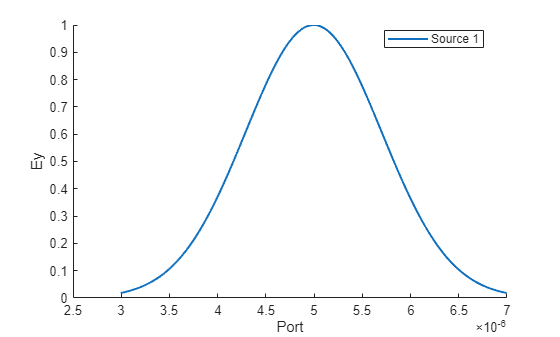

w0 = 1e-6; % waist
modelGC.addSource('GaussianBeam', w0);
modelGC.setSource.setAngle(30);
modelGC.setSource.setAmplitude(1);
modelGC.cfg.source.dispProfile('Ey');

### Step 6: FDFD 2D scattering simulation

To simulate the scattering behavior of the directional coupler, the device must be fully meshed, and the input source properly configured. 

modelGC.dispInfo;

=== Model2D Information ===
Wavelength   : 1.550e-06 m
Plane Label  : zx
Background   : eps_r=1.000, mu_r=1.000
Mesh         : z: N=300, d=2.000e-08 m
               x: N=1175, d=1.000e-08 m
Solver       : Scattering
BC (z)     : PML, thickness=10
BC (x)     : PML, thickness=10
Source Polarization : TE
Source Port         : dir=-z
                      position (z) = 3.000e-06 m
                      span (x)     = [3.000e-06, 7.000e-06] m


modelGC.solveModel;

Model object has been solved successfully.


The simulation is executed, and we can export the solution and visualize the scattering field amplitude distribution.

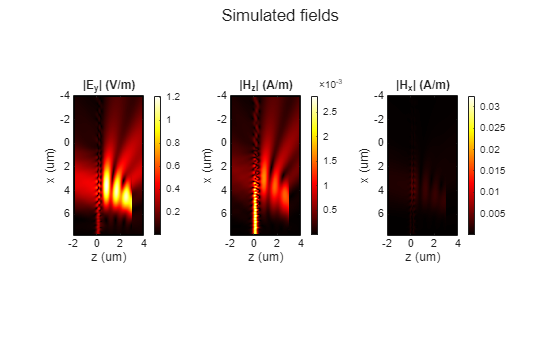

results = modelGC.exportResults;

figure; sgtitle('Simulated fields')
subplot(1,3,1);
imagesc(results.z*1e6, results.x*1e6, abs(results.Ey).');
xlabel('z (um)'), ylabel('x (um)'); axis image;
title('|E_y| (V/m)');
colormap hot; colorbar;
subplot(1,3,2);
imagesc(results.z*1e6, results.x*1e6, abs(results.Hz).');
xlabel('z (um)'), ylabel('x (um)'); axis image;
title('|H_z| (A/m)');
colormap hot; colorbar;
subplot(1,3,3);
imagesc(results.z*1e6, results.x*1e6, abs(results.Hx).');
xlabel('z (um)'), ylabel('x (um)'); axis image;
title('|H_x| (A/m)');
colormap hot; colorbar;